# ROZWIĄZYWANIE RÓWNAŃ NIELINIOWYCH

## PARAMETRY LOKALNEJ ZBIEŻNOŚCI

Na początek zajmijmy się współczynnikiem lokalnej zbieżności *C*:


$$\Delta_{i+1} =C\Delta_i^{\rho }$$


W celu zrozumienia czym jest współczynnik lokalnej zbieżności posłużymy się dwiema metodami o wykładniku lokalnej zbieżności $\rho =1$ - metodą bisekcji i metodą *regula falsi*. Jedyna różnica między tymi dwiema metodami polega na różnicy we współczynniku lokalnej zbiezności i jego ewentualnej zależności od funkcji i punktu startowego.

Wyrysujmy zbieżność naszego algorytmu dla tych dwóch przypadków osobno:

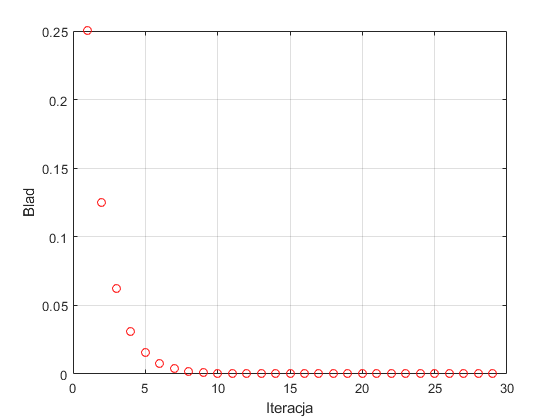

% Do rozwiązania przyjmiemy prostą funkcję o oczywistym rozwiązaniu
% teoretycznym
% f = @(x) (x-1).*(x-2).*(x-5);
f = @(x) x^50*exp(-x) - 100;
true_root = 1.121346658722935;
% Pierwszy testy wykonamy dla metody bisekcji
options.imax = 100;    %w ten sposób ustawiamy maksymalna ilość iteracji
options.return_all = true;  % ta flaga powoduje zwrócenie wyników pośrednich w kolejnych iteracjach
options.TOL = 1e-8; % zakładana dokładność
options.warnings = true; % dostaniemy warning w przypadku jakby coś poszło nie tak

% Ustalamy właściwe warunki startowe dla bisekcji
a = 0;
b = 1.5;

% Uruchamiamy implementację
[resultsBisection] = calculateBisectionSolution(f,a,b,options);

%Obliczamy błąd rozwiązania w kolejnych iteracjach (znajac rzowiązanie
%prawdziwe)
errorBisection = abs(resultsBisection - true_root);
plot(errorBisection, 'ro'); xlabel('Iteracja'); ylabel('Blad'); grid on;

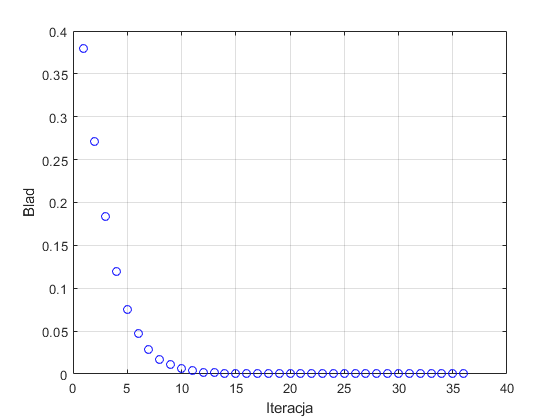


% Powtarzamy procedurę dla metody regula falsi
[resultsFalsePosition] = calculateFalsePositionSolution(f,a,b,options);
errorFalsePosition = abs(resultsFalsePosition - true_root);
plot(errorFalsePosition, 'bo');xlabel('Iteracja'); ylabel('Blad'); grid on;

Zastanówmy się teraz jak interpretować te wyniki oddzielnie. Wiemy, że obie metody mają zbiezność liniową $\rho =1$ a jednak wykresy błędu nie wyglądają liniowo. Aby to wyjaśnić przypomnijmy sobie definicję wykładnika lokalnej zbieżności:


$$\Delta_{i+1} =C\Delta_i^{\rho }$$


aby zatem zobaczyć liniową zależność należałoby wyrysować zależność między błędem w poprzedniej iteracji a błędem w obecnej. Natomiast my mamy wyrysowaną zależność błędu od numeru iteracji.

Wyrysujmy zatem wykres tak, żeby zobaczyć zależność liniową dla obu metod:

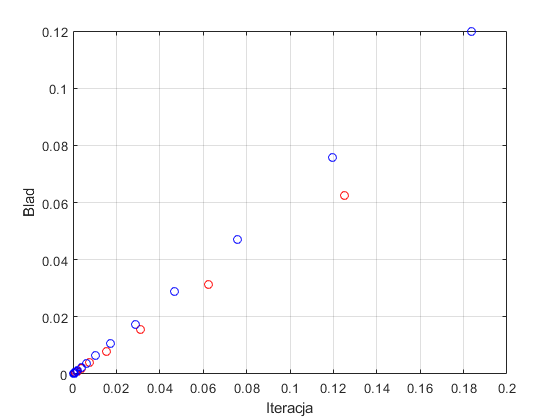

% generacja wektorów błędu (poprzedniego i bieżącego)
oldBisectionError = errorBisection(1:end-1);
newBisectionError = errorBisection(2:end);

plot(oldBisectionError, newBisectionError, 'ro'); hold on;

oldFalsePositionError = errorFalsePosition(1:end-1);
newFalsePositionError = errorFalsePosition(2:end);

plot(oldFalsePositionError, newFalsePositionError, 'bo');xlabel('Błąd w poprzedniej iteracji'); ylabel('Błąd w obecnej iteracji'); grid on;
axis([0 0.2 0 0.12]); hold off

Jak widać zależność w obu przypadkach jest liniowa. Różnice w nachyleniu wydają się być niewielkie, ale są znaczące. 

Zwróć na początek uwagę na wykres dla metody bisekcji (czerwony). Ta prosta ma dokładnie nachylenie 0.5 - unikalną cechą metody bisekcji jest to, że ta wartość nie zależy od danych wejściowych.

**ĆWICZENIE 1**

Zmodyfikuj powyższy kod, zawężając przedział startowy [a,b] tak, aby leżał coraz bliżej jedynego pierwiastka tej funkcji (x ≈ 1.1213), i porównaj, jak zmienia się liczba iteracji potrzebnych do osiągnięcia zadanej dokładności w zależności od szerokości przedziału startowego.

Wróć do oryginalnych ustawień (a=0, b=1.5, true_root=1.121346658722935). Wykonaj pierwszą część kodu powyżej.

Teraz zaobserwujemy kolejny efekt numeryczny:

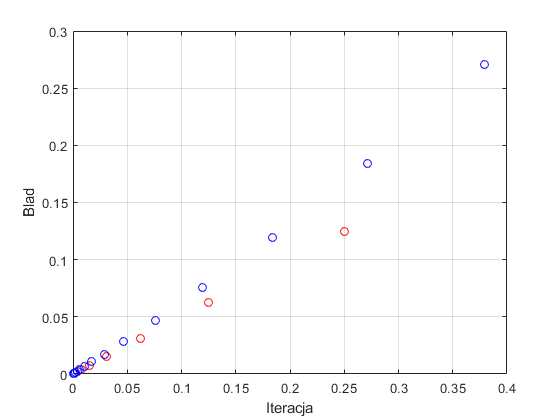

% generacja wektorów błędu (poprzedniego i bieżącego)
oldBisectionError = errorBisection(1:end-1);
newBisectionError = errorBisection(2:end);

plot(oldBisectionError, newBisectionError, 'ro'); hold on;

oldFalsePositionError = errorFalsePosition(1:end-1);
newFalsePositionError = errorFalsePosition(2:end);

plot(oldFalsePositionError, newFalsePositionError, 'bo');xlabel('Błąd w poprzedniej iteracji'); ylabel('Błąd w obecnej iteracji'); grid on;
hold off

Jak widzisz dla dalszych iteracji zależność liniowa się "rozpada". Dzieje się tak dlatego, że w przypadku liniowego, bardzo wolnozbieżnego algorytmu zachodzi ciągła propagacja błędu (taka o jakiej mówiliśmy w pierwszej części zajęć). Im więcej iteracji musi zrobić algorytm, tym bardziej początkowe błędy zaokrągleń i reprezentacji są propagowane przez algorytm. W skrajnym przypadku mogą nie pozwolić na uzyskanie wyniku w ogóle.

Błędy te nie podlegają redukcji w algorytmach iteracyjnych (zmniejszają one wyłącznie błędy metody). Dlatego poza wyjątkowymi sytuacjami, kiedy jakaś metoda jest liniowa raczej jej nie stosujemy, chyba, że ma  jakieś bardzo przydatne właściwości jak np. stały współczynnik zbieżności w przypadku bisekcji.

**ĆWICZENIE 2:**

Wiedząc, że dla metody *regula falsi* współczynnik zbieżności jest uzależniony od funkcji oryginalnej zgodnie z wyrażeniem:


$$C=\frac{f^{\prime \prime } \left(y_{\infty } \right)}{2f^{\prime } \left(y_{\infty } \right)}$$


Dobierz tak funkcję w powyższych kodach, aby metoda *regula falsi *dawała wynik zbieżności lepszy od metody bisekcji.

**ĆWICZENIE 2 (cont.):**

Powtórz ćwiczenie 1 tak, żeby metoda *regula falsi* była rozbieżna (w ogóle nie dawała wyniku)